k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 4

k = 4

k = 4

k = 4

k = 4

k = 4

k = 4

k = 4

k = 4

k = 4

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 6

k = 6

k = 6

k = 7

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 5

k = 6

k = 6

k = 6

k = 6

k = 6

k = 6

k = 6

k = 6

k = 6

k = 6

k = 6

k = 7

k = 7

k = 7

k = 7

k = 6

k = 6

k = 8

k = 8

k = 6

k = 6

k = 6

k = 6

k = 6

k = 7

k = 8

k = 8

k = 8

k = 5

k = 6

k = 9

k = 8

k = 7

k = 12

k = 9

k = 8

k = 8

k = 7

k = 10

k = 9

k = 8

k = 10

k = 19

k = 340

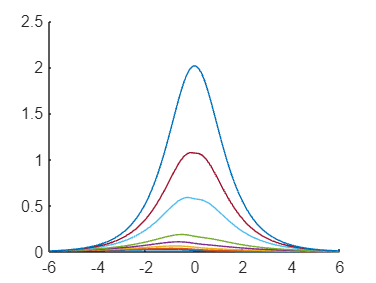

clear
i=1;
error=0.0000000001;
C=zeros(100,1);
aC=zeros(100,1);
for a=0.01:0.01:1
    span=6;
    yspan=[-span span];
    k=0;
    u0=[0.01,a*0.01];
    c0=complex(0,0.7);
    sol=ode45(@(y,u) func(y,u,c0,a),yspan,u0);
    U=deval(sol,span);
    A0=U(2)+(U(1)*a);
    c1=complex(0,0.10);
    sol=ode45(@(y,u) func(y,u,c1,a),yspan,u0);
    U=deval(sol,span);
    A1=U(2)+(U(1)*a);
    c=(c1-((A1*(c1-c0))/(A1-A0))); 
    while abs(A1-A0)>error
        sol=ode45(@(y,u) func(y,u,c,a),yspan,u0);
        U=deval(sol,span);
        A0=A1;
        A1=U(2)+(U(1)*a);
        c0=c1;
        c1=c;
       c=(c1-((A1*(c1-c0))/(A1-A0)));
        k=k+1;
    end
    k
    C(i)=imag(c);
    aC(i)=a*imag(c);
    i=i+1;
z=linspace(-span,span,100)';
x=deval(sol,z);hold on
if isreal(a*10) && rem(a*10,1)==0
plot(z,x(1,:));
end
hold off
end

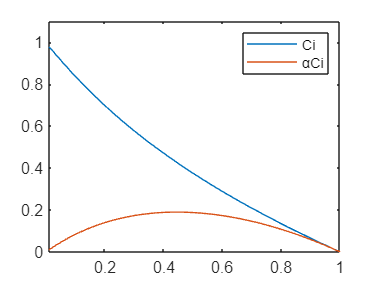

t=linspace(0.01,1,100)';
plot(t,C)
hold on
plot(t,aC)
hold off
ylim([0 1.1]);
xlim([0.01 1]);
legend('Ci','αCi');

function dudy=func(y,u,c,a)
    dudy=zeros(2,1);
    dudy(1,1)=u(2);
    dudy(2,1)=((a^2)+((2*tanh(y)*((tanh(y))^2 - 1))/(tanh(y)-c)))*u(1);
end